% mikexcohen@gmail.com

## TF of many trials: the painful, slow, and redundant way

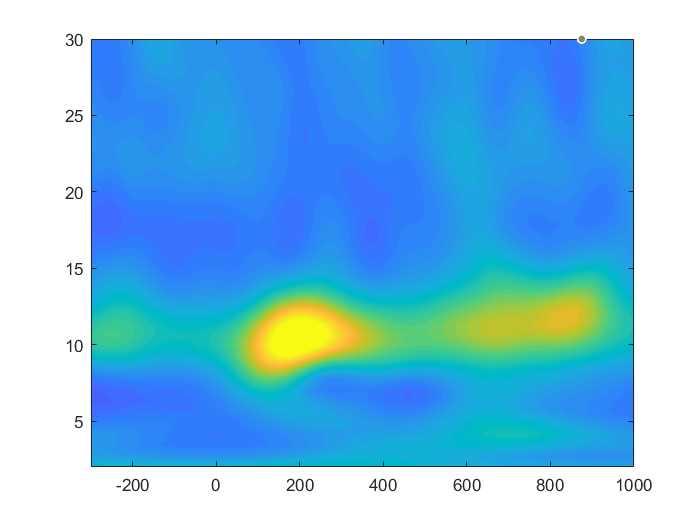

load sampleEEGdata.mat

% frequency parameters
min_freq =  2;
max_freq = 30;
num_frex = 40;
frex = linspace(min_freq,max_freq,num_frex);

% which channel to plot
channel2use = 'o1';

% other wavelet parameters
range_cycles = [ 4 10 ];

s = logspace(log10(range_cycles(1)),log10(range_cycles(end)),num_frex) ./ (2*pi*frex);
wavtime = -2:1/EEG.srate:2;
half_wave = (length(wavtime)-1)/2;

tic; % start matlab timer

% FFT parameters
nWave = length(wavtime);
nData = EEG.pnts;
nConv = nWave + nData - 1;

% initialize output time-frequency data
tf = zeros(length(frex),EEG.pnts,EEG.trials);

% loop over frequencies
for fi=1:length(frex)
    
    % create wavelet and get its FFT
    % the wavelet doesn't change on each trial...
    wavelet  = exp(2*1i*pi*frex(fi).*wavtime) .* exp(-wavtime.^2./(2*s(fi)^2));
    waveletX = fft(wavelet,nConv);
    waveletX = waveletX ./ max(waveletX);
    
    % now loop over trials...
    for triali=1:EEG.trials
        
        dataX = fft(squeeze(EEG.data(strcmpi(channel2use,{EEG.chanlocs.labels}),:,triali)), nConv);
        
        % run convolution
        as = ifft(waveletX .* dataX);
        as = as(half_wave+1:end-half_wave);
    
        % put power data into big matrix
        tf(fi,:,triali) = abs(as).^2;
    end
end

tfTrialAve = mean(tf,3);

computationTime = toc; % end matlab timer for this cell

% plot results
figure(1), clf
contourf(EEG.times,frex,tfTrialAve,40,'linecolor','none')
set(gca,'clim',[0 5],'ydir','normal','xlim',[-300 1000])

## now let's try it again using trial concatenation

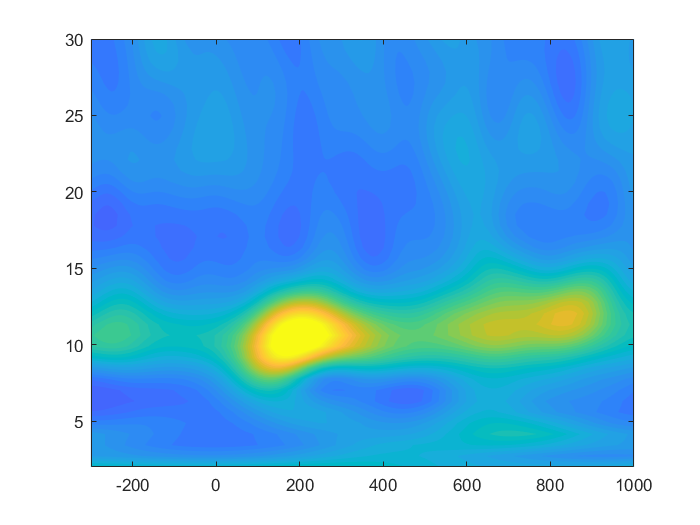

tic; % restart matlab timer

% FFT parameters
nWave = length(wavtime);
nData = EEG.pnts * EEG.trials; % This line is different from above!!
nConv = nWave + nData - 1;

% initialize output time-frequency data
tf = zeros(length(frex),EEG.pnts);

% now compute the FFT of all trials concatenated
alldata = reshape( EEG.data(strcmpi(channel2use,{EEG.chanlocs.labels}),:,:) ,1,[]);
dataX   = fft( alldata ,nConv );


% loop over frequencies
for fi=1:length(frex)
    
    % create wavelet and get its FFT
    % the wavelet doesn't change on each trial...
    wavelet  = exp(2*1i*pi*frex(fi).*wavtime) .* exp(-wavtime.^2./(2*s(fi)^2));
    waveletX = fft(wavelet,nConv);
    waveletX = waveletX ./ max(waveletX);
    
    % now run convolution in one step
    as = ifft(waveletX .* dataX);
    as = as(half_wave+1:end-half_wave);
    
    % and reshape back to time X trials
    as = reshape( as, EEG.pnts, EEG.trials );
    
    % compute power and average over trials
    tf(fi,:) = mean( abs(as).^2 ,2);
end

computationTime(2) = toc; % end matlab timer

% plot results
figure(2), clf
contourf(EEG.times,frex,tf,40,'linecolor','none')
set(gca,'clim',[0 5],'ydir','normal','xlim',[-300 1000])

## show computation time differences

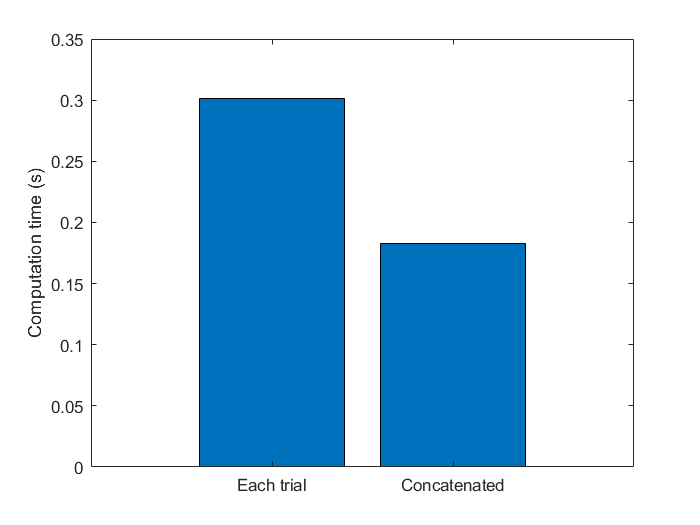

figure(3), clf
bar(computationTime)
set(gca,'xtick',1:2,'xticklabel',{'Each trial';'Concatenated'},'xlim',[0 3])
ylabel('Computation time (s)')

## show differences

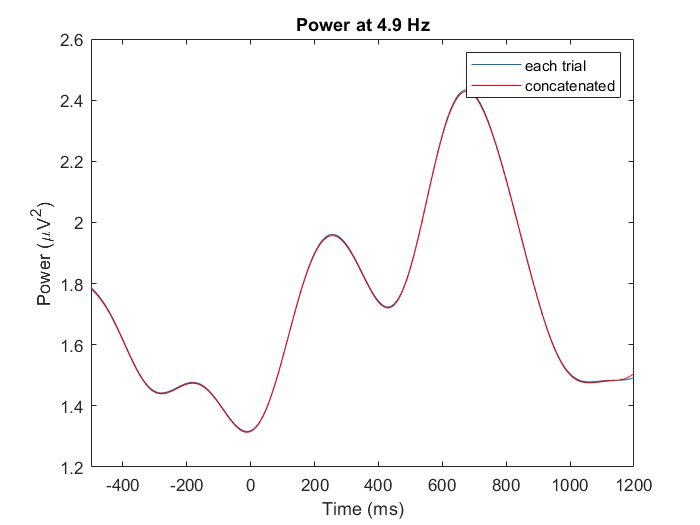

figure(4), clf
plot(EEG.times,tfTrialAve(5,:)), hold on
plot(EEG.times,tf(5,:),'r')
set(gca,'xlim',[-500 1200])

title([ 'Power at ' num2str(round(10*frex(5))/10) ' Hz' ])
xlabel('Time (ms)'), ylabel('Power (\muV^2)')
legend({'each trial';'concatenated'})

## end